# **Interpolare Lagrange**

P1. Implementati o rutina pentru calculul valorilor polinomului de interpolare Lagrange cand se dau punctele, nodurile si valorile functiei in noduri.

% Test pentru interpolarea Lagrange
x_nodes = [0, 1, 2, 3];
y_nodes = [1, 3, 2, 4];
x_eval = [0.5, 1.5, 2.5];
y_interp = lagrange_interpolation(x_nodes, y_nodes, x_eval);
disp('Valori interpolate:');

Valori interpolate:


disp(y_interp);

    2.7500    2.5000    2.2500



P2. Reprezentati grafic polinoamele fundamentale cand se dau gradul si nodurile.

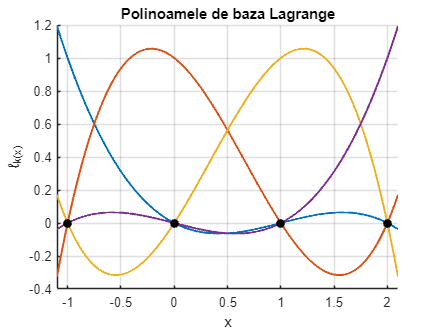

% Test pentru reprezentarea polinoamelor de baza
x_nodes = [-1, 0, 1, 2];
plot_lagrange_basis(x_nodes);

 P3. Reprezentati pe acelasi grafic f si Lmf

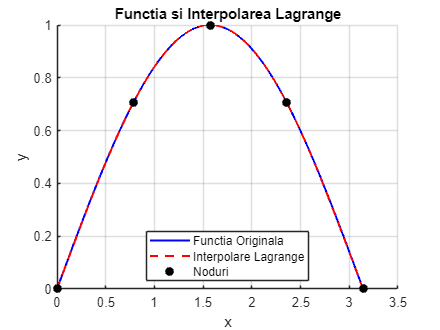

% Test pentru reprezentarea functiei si a interpolarii
f = @(x) sin(x);
x_nodes = [0, pi/4, pi/2, 3*pi/4, pi];
plot_function_and_interpolation(f, x_nodes, 0, pi);

P4. Dandu-se x, f, m si nodurile, aproximati f(x) utilizand interpolarea Lagrange.

% Test pentru aproximarea valorii f(x) cu interpolare Lagrange
f = @(x) exp(x);
x_nodes = [-1, -0.5, 0, 0.5, 1];
f_values = f(x_nodes);
x_eval = 0.25;

y_approx = lagrange_approx_for_function(x_nodes, f_values, x_eval);

fprintf('Aproximarea lui f(%.2f) folosind interpolare Lagrange: %.10f\n', x_eval, y_approx);

Aproximarea lui f(0.25) folosind interpolare Lagrange: 1.2836319705


fprintf('Valoarea exacta: %.10f\n', f(x_eval));

Valoarea exacta: 1.2840254167


fprintf('Eroare: %.10e\n', abs(f(x_eval) - y_approx));

Eroare: 3.9344614888e-04


P5. Implementati metoda baricentrica, in cazul general si pentru noduri Chebisev #1 si #2.

% Test pentru interpolarea baricentrici
x_nodes = [0, 1, 2, 3];
y_nodes = [1, 3, 2, 4];
x_eval = [0.5, 1.5, 2.5];
y_interp = barycentric_interpolation(x_nodes, y_nodes, x_eval);
disp('Valori interpolate (metoda baricentrici):');

Valori interpolate (metoda baricentrici):


disp(y_interp);

    2.7500    2.5000    2.2500




% Test pentru nodurile Cebisev
n = 5;
a = -1;
b = 1;
nodes1 = chebyshev_nodes_1(n, a, b);
nodes2 = chebyshev_nodes_2(n, a, b);
disp('Noduri Cebisev de speta 1:');

Noduri Cebisev de speta 1:


disp(nodes1);

    0.9511    0.5878    0.0000   -0.5878   -0.9511



disp('Noduri Cebisev de speta 2:');

Noduri Cebisev de speta 2:


disp(nodes2);

    1.0000    0.7071    0.0000   -0.7071   -1.0000



## Probleme practice

P1. Datele de mai jos dau populatia SUA in perioada 1900–2000 (in milioane de locuitori):

t       y

1900    75.995  

1910    91.972  

1920   105.711  

1930   123.203  

1940   131.669  

1950   150.697  

1960   179.323  

1970   203.212  

1980   226.505  

1990   249.633  

2000   281.422  

2010   308.786

Approximati populatia din 1975 si 2018.

Populatia estimata a SUA:
1975: 214.858 milioane
2018: 318.697 milioane


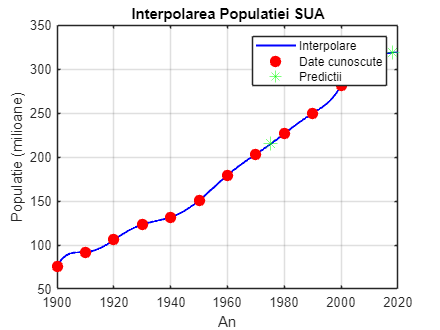

us_population();

P2. Fie

f(x) = e^(x^2)-1

Approximati f(1.25) utilizand valorile lui f in 1, 1.1, 1.2, 1.3 si 1.4, si dati o delimitare a erorii.

Problema 2: Aproximarea lui f(1.25) pentru f(x) = e^(x^2-1)

Valorile functiei in noduri:
f(1.0) = 1.0000000000
f(1.1) = 1.2336780600
f(1.2) = 1.5527072185
f(1.3) = 1.9937155332
f(1.4) = 2.6116964734

Aproximarea lui f(1.25) folosind interpolare Lagrange: 1.7549573289
Valoarea exacta: f(1.25) = 1.7550546570
Eroarea absoluta: |f(1.25) - L(1.25)| = 9.7328098152e-05

Delimitarea erorii:
|f(1.25) - L(1.25)| <= (M_5/5!) * |w_5(1.25)|
M_5 (maximul derivatei de ordin 5 pe [1, 1.4]) = 2.0348868013e+03
|w_5(1.25)| = |(1.25-1)(1.25-1.1)(1.25-1.2)(1.25-1.3)(1.25-1.4)| = 1.4062500000e-05
Delimitarea erorii: 2.3846329703e-04

Verificare: Eroarea absoluta (9.7328098152e-05) <= Delimitarea erorii (2.3846329703e-04): true


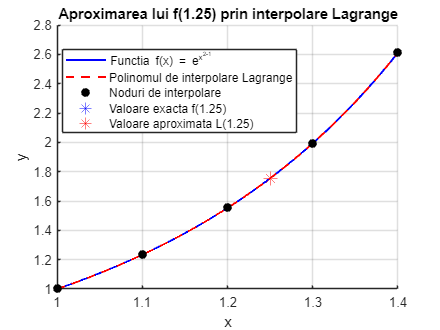

aproximare_f_125();

P3. Aproximati √115 cu 3 zecimale exacte prin interpolare Lagrange.

approximate_sqrt115();

Aproximarea lui √115:
Interpolare Lagrange: 10.7227555054
Valoarea exacta: 10.7238052948
Eroare: 1.0497893994e-03
Aproximare cu 3 zecimale: 10.723


P4. Dati contraexemple pentru convergenta interpolarii Lagrange si studiati-le grafic:

(a) Contraexemplul lui Runge:

 f:[-5,5] -> R, f(x) = 1/(1+x^2);�

(b) Contraexemplul lui Bernstein:

g:[-1,1] -> R, g(x) = |x|;

Ambele cu:

- noduri echidistante, si

- noduri Chebyshev de speta a doua.

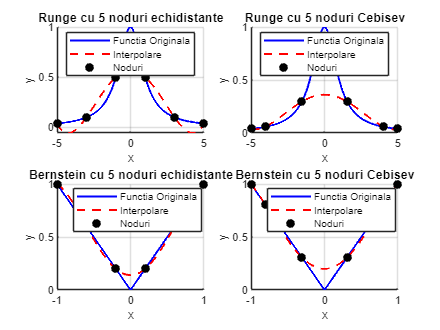

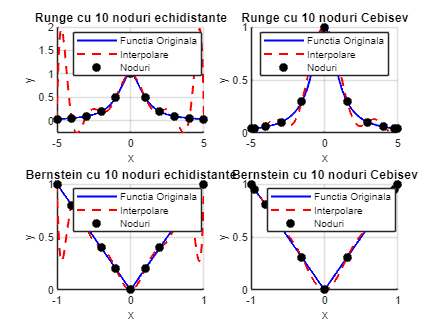

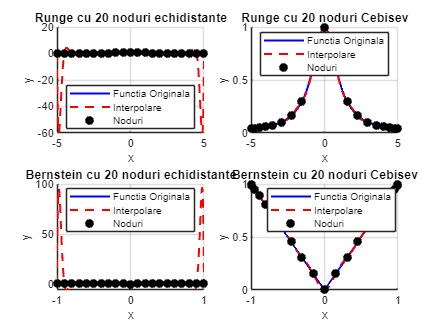

runge_bernstein_counterexamples();

P5. Aproximati sin(5°) si cos(5°) folosind interpolarea Lagrange si tabela de valori:

approximate_trig();

Aproximarea lui sin(5°):
Interpolare Lagrange: 0.0869134109
Valoare exacta: 0.0871557427
Eroare: 2.4233185860e-04

Aproximarea lui cos(5°):
Interpolare Lagrange: 0.9963861960
Valoare exacta: 0.9961946981
Eroare: 1.9149789616e-04
